% understanding image basic 'image resize'
% extraction of color band
% creating a synthetic imageall
% pseudocolor image

% step0: clear workspace and cmd
% step1: read img
% step2: img resize
% step3: img type conversion
% step4: img pixel info
% step5: extraction of color band
% step6: create a synthetic img

clc;
clear;
close all;

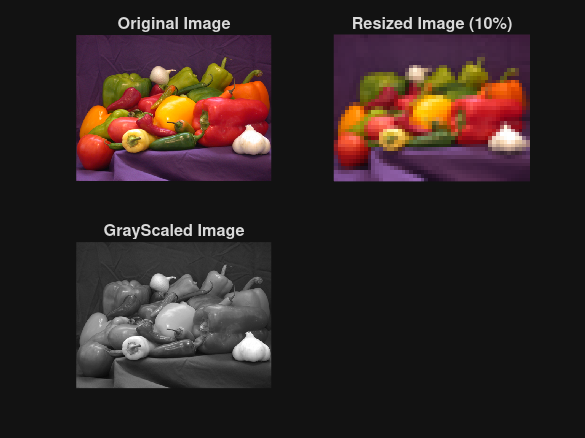

img = imread('peppers.png');
subplot(2, 2, 1);
imshow(img);
title('Original Image');

img_resize = imresize(img, 0.1);
subplot(2, 2, 2);
imshow(img_resize);
title('Resized Image (10%)');

img_gray = rgb2gray(img);
subplot(2, 2, 3);
imshow(img_gray);
title('GrayScaled Image');

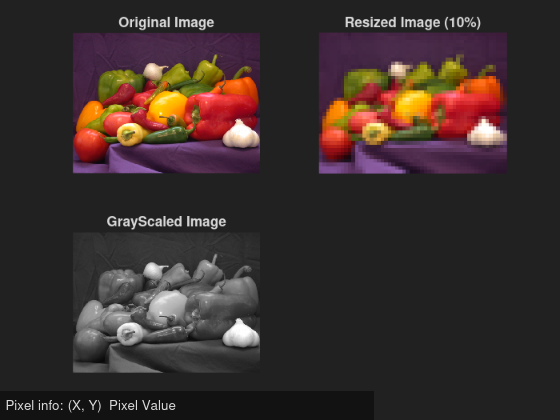

impixelinfo;

img_double = im2double(img_gray);
disp('First 5 values in double grayscale image');

First 5 values in double grayscale image


disp(img_double(1, 1: 5));

    0.1686    0.1725    0.1804    0.1725    0.1647



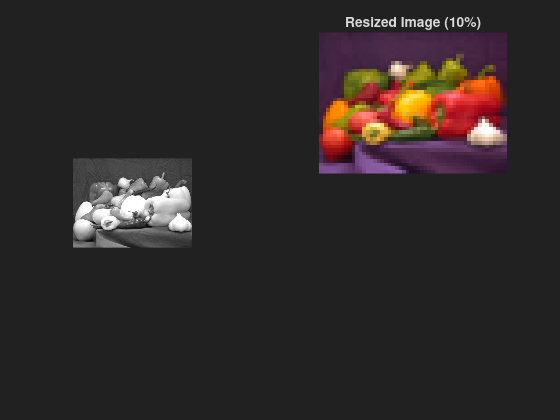

R = img(:, :, 1);
subplot(1, 3, 1);
imshow(R);

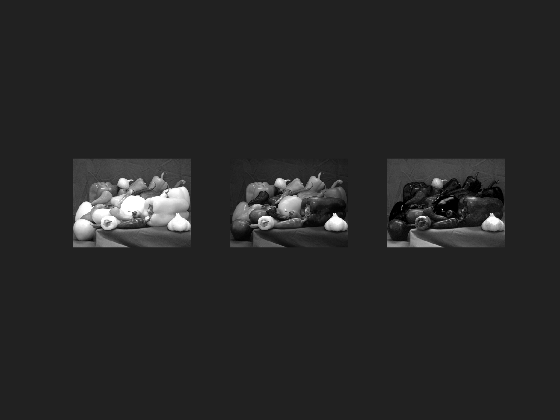

G = img(:, :, 2);
subplot(1, 3, 2);
imshow(G);
B = img(:, :, 3);
subplot(1, 3, 3);
imshow(B);

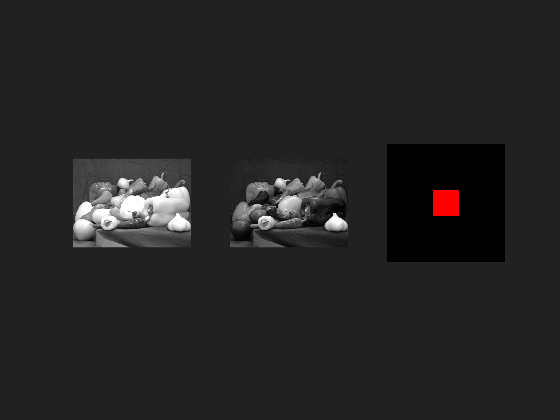

S_img = zeros(256, 256, 3, 'uint8');img_gray = rgb2gray(img);
S_img(100: 156, 100: 156, 1) = 255;
imshow(S_img);